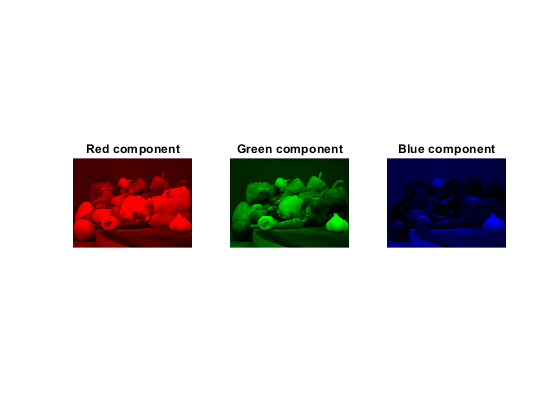

peppers_img=imread('peppers.png');

%-----------------------------------------------------------------------

%Extracting the three color components

red_component=peppers_img(:,:,1);%red component of the image
green_component=peppers_img(:,:,2);%green component of the image
blue_component=peppers_img(:,:,3);%red component of the imageSeS

%---------------------------------------------------------------------

%Creating a black image

Black= zeros(size(peppers_img,1),size(peppers_img,2));

%---------------------------------------------------------------------

%Creating colored images of the image

red_image =cat(3,red_component,Black,Black);
green_image =cat(3,Black,green_component,Black);
blue_image =cat(3,Black,Black,blue_component);

%---------------------------------------------------------------------

%Displaying color components 

subplot(1,3,1)
imshow (red_image)
fontsize= 18;
title('Red component');
subplot(1,3,2)
imshow (green_image)
fontsize= 18;
title('Green component');

subplot(1,3,3)
imshow (blue_image)
fontsize= 18;
title('Blue component');

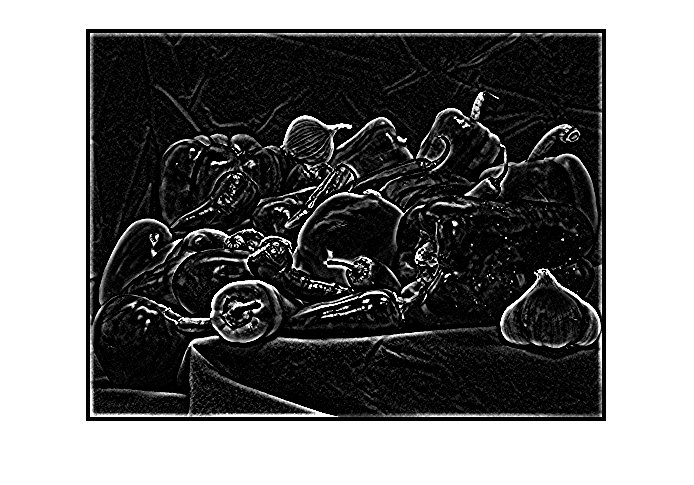


%-----------------------------------------------------------

%getting a gray image out of the original one
grey_image=rgb2gray(peppers_img);

%-----------------------------------------------------------

%Converting image components into double
 Red_double=im2double(red_component);
 Blue_double=im2double(blue_component);
 Green_double=im2double(green_component);
 Gray_double= im2double(grey_image);

 %---------------------------------------------------------
 
%Edge Detection
Edge_Detection_kernel=[
    0   0   0    0    -1  0   0   0  0
    0   0   0    0,  -1  ,0   0   0  0 ;
    0   0   0    0   -1   0   0   0  0;
    0   0   0    0   -1   0   0   0  0;
   -1  -1  -1   -1   16  -1  -1  -1 -1;
    0   0   0    0   -1   0   0   0  0 ;
    0   0   0    0   -1   0   0   0  0 ;
    0   0   0    0   -1   0   0   0  0;
    0   0   0    0   -1   0   0   0  0 ];


%--------------------------

%Edge detection for a gray image

Gray_edge_detection = conv2( Gray_double,Edge_Detection_kernel); 
figure;
imshow(Gray_edge_detection);

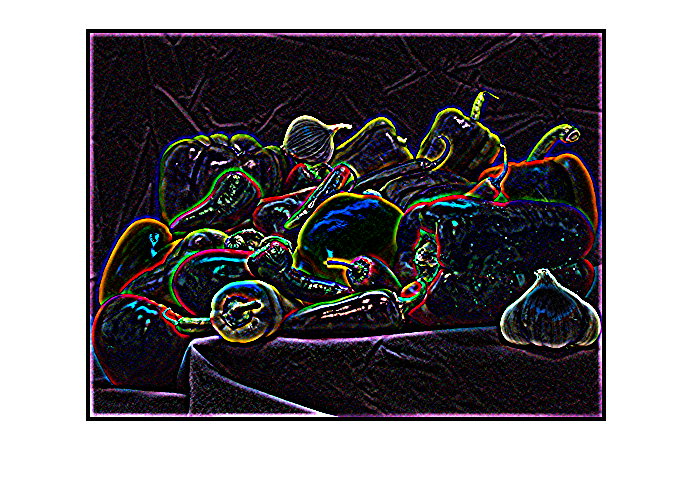


%--------------------------
%Edge detection for the original image
figure;
Red_edge_detectioned_image=conv2(Red_double,Edge_Detection_kernel);
Blue_edge_detectioned_image=conv2(Blue_double,Edge_Detection_kernel);
Green_edge_detectioned_image=conv2(Green_double,Edge_Detection_kernel);

Img_processed =cat(3,Red_edge_detectioned_image,Green_edge_detectioned_image,Blue_edge_detectioned_image);
imshow(Img_processed);

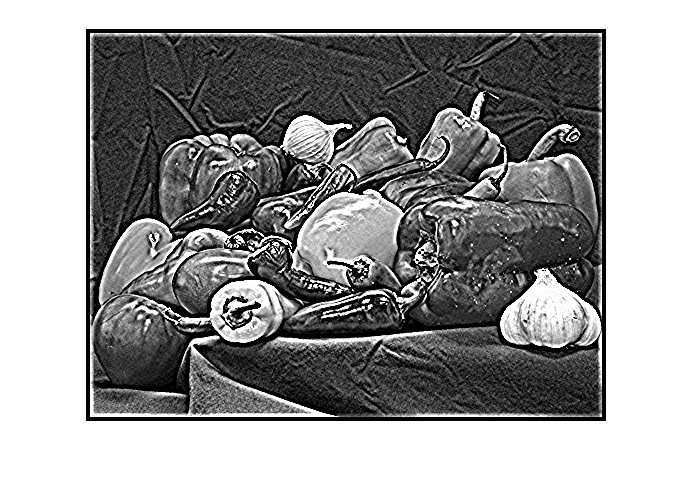



%--------------------------------------------------------


%Sharpining image

Sharpening_Kernel =[0   0   0    0   -1   0   0   0  0 ;
    0   0   0    0,  -1  ,0   0   0  0 ;
    0   0   0    0   -1   0   0   0  0 ;
    0   0   0    0   -1   0   0   0  0 ;
   -1  -1  -1   -1   17  -1  -1  -1 -1 ;
    0   0   0    0   -1   0   0   0  0 ;
    0   0   0    0   -1   0   0   0  0 ;
    0   0   0    0   -1   0   0   0  0 ;
    0   0   0    0   -1   0   0   0  0 ];


%----------------------------

%%Sharpening the gray image

Gray_sharpened_image = conv2( Gray_double,Sharpening_Kernel);
figure;
imshow(Gray_sharpened_image);

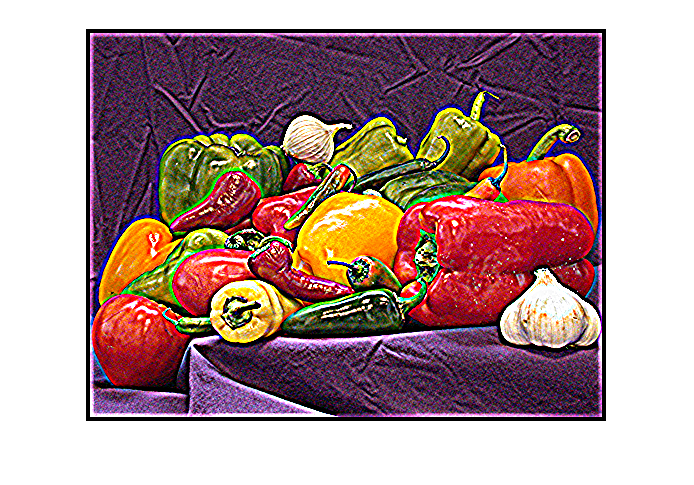


%------------------------------

%%Sharping the original image

figure;
Red_sharpened_image=conv2(Red_double,Sharpening_Kernel);
Blue_sharpened_image=conv2(Blue_double,Sharpening_Kernel);
Green_sharpened_image=conv2(Green_double,Sharpening_Kernel);

Sharpened_image =cat(3,Red_sharpened_image,Green_sharpened_image,Blue_sharpened_image);
imshow(Sharpened_image);

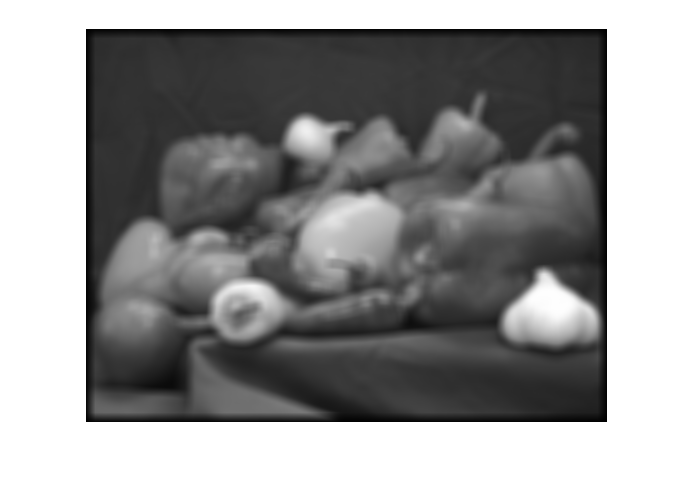



%--------------------------------------------------------------


% Bluring image

Gz=(1/100 )*ones(10,10);

%------------------------

%Bluring the gray image
Blured_gray_image = conv2( Gray_double,Gz);
figure;
imshow(Blured_gray_image);

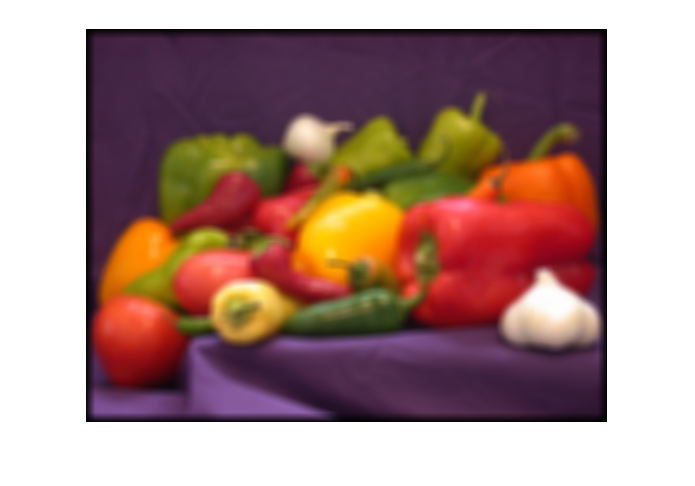


%-------------------------

%Bluring the original image

figure;

Blured_red_image=conv2(Red_double,Gz);
Blured_blue_image=conv2(Blue_double,Gz);
Blured_green_image=conv2(Green_double,Gz);

Blured_image =cat(3,Blured_red_image,Blured_green_image,Blured_blue_image);
imshow(Blured_image);



%-------------------------------------------------------

%Motion bluring 

Motion_bluring_kernel=(1/50)*ones(1,50)

Motion_bluring_kernel =     0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200


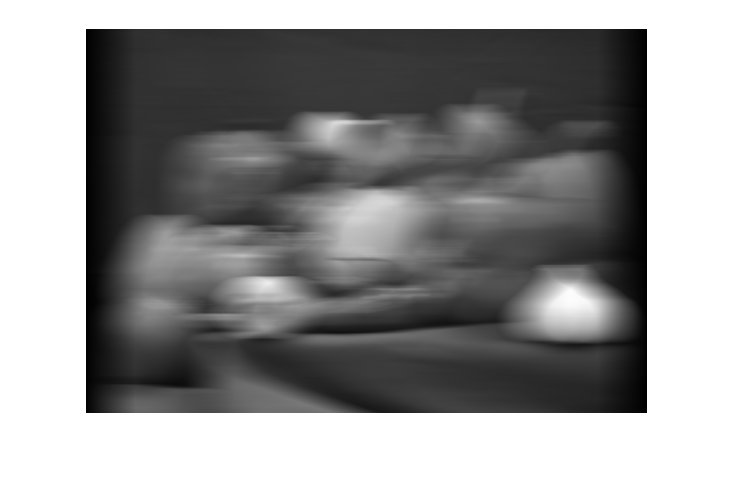


%----------------------------

%Motion blur of gray image

Motion_blured_gray_image = conv2( Gray_double,Motion_bluring_kernel);
figure;
imshow(Motion_blured_gray_image);

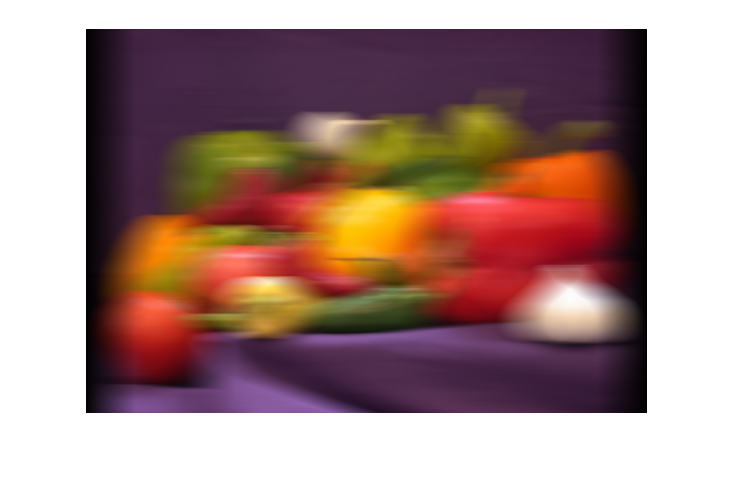


%-----------------------------

%Motion blur of the original image


figure;

Motion_blured_red_image=conv2(Red_double,Motion_bluring_kernel);
Motion_blured_blue_image=conv2(Blue_double,Motion_bluring_kernel);
Motion_blured_green_image=conv2(Green_double,Motion_bluring_kernel);

Motion_blured_image =cat(3,Motion_blured_red_image,Motion_blured_green_image,Motion_blured_blue_image);
imshow(Motion_blured_image);

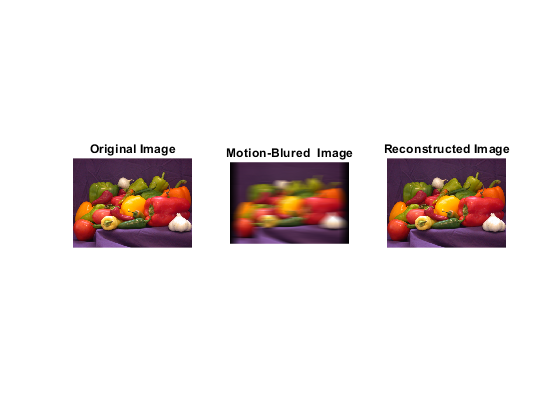


%---------------------------------------------------------------

%Adjusting the size of the motion_bluring kernel to suit the divisioin in
%frequency domain

The_widened_motion_bluring_kernel=zeros(size(Motion_blured_image,1),size(Motion_blured_image,2));
The_widened_motion_bluring_kernel(1,1:50)=Motion_bluring_kernel;


%-------------------------------------------------------------------

%Reconstructing the image from the motion-blured one in frequency domain

%Converting into Fourier domain

Frequency_domain_motion_blured_kernel=fft2(The_widened_motion_bluring_kernel);
Frequency_domain_motion_blured_red_image=fft2(Motion_blured_red_image);
Frequency_domain_motion_blured_blue_image=fft2(Motion_blured_blue_image);
Frequency_domain_motion_blured_green_image=fft2(Motion_blured_green_image);
Frequency_domain_motion_blured_gray_image=fft2(Motion_blured_gray_image);

%---------------------------------------


%Getting the original image in fourier domain


reconstructed_red_in_frequendy_domain=Frequency_domain_motion_blured_red_image./Frequency_domain_motion_blured_kernel;
reconstructed_blue_in_frequency_domain=Frequency_domain_motion_blured_blue_image./Frequency_domain_motion_blured_kernel;
reconstructed_green_in_frequency_domain=Frequency_domain_motion_blured_green_image./Frequency_domain_motion_blured_kernel;
reconstructed_gray_in_frequency_domain=Frequency_domain_motion_blured_gray_image./Frequency_domain_motion_blured_kernel;

%-----------------------------------------

%Getting inverse Fourier Transform of the image

Reconstructed_red=ifft2(reconstructed_red_in_frequendy_domain);
Reconstructed_green=ifft2(reconstructed_green_in_frequency_domain);
Reconstructed_blue=ifft2(reconstructed_blue_in_frequency_domain);
Reconstructed_gray=ifft2(reconstructed_gray_in_frequency_domain);

Reconstructed_gray=Reconstructed_gray(1:384,1:512,:);
%------------------------------------------

%The reconstructed image

Reconstructed_image=cat(3,Reconstructed_red,Reconstructed_green,Reconstructed_blue);

Reconstructed_image=Reconstructed_image(1:384,1:512,:);

%-------------------------------------

%displaying the original image besides the motion_blured and reconstructed
%one

figure;
subplot(1,3,1);
imshow (peppers_img);
fontsize= 18;
title('Original Image');

subplot(1,3,2);
imshow (Motion_blured_image);
fontsize= 18;
title('Motion-Blured  Image');

subplot(1,3,3);
imshow (Reconstructed_image);
fontsize= 18;
title('Reconstructed Image');

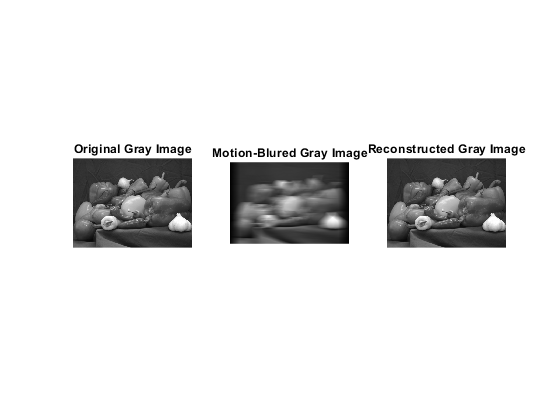


figure;
subplot(1,3,1);
imshow (grey_image);
fontsize= 18;
title('Original Gray Image');

subplot(1,3,2);
imshow (Motion_blured_gray_image);
fontsize= 18;
title('Motion-Blured Gray Image');

subplot(1,3,3);
imshow (Reconstructed_gray);
fontsize= 18;
title('Reconstructed Gray Image');



%-------------------------------------------------------------------------%

%--------------------Thank  you doctor Michael----------------------------%





